# **IO751 & IO752 - PROFINET Loopback**

The IO751 and IO752 are PROFINET I/O modules to connect real-time target machines to industrial equipment. The IO751 is a PROFINET Controller module that is used to communicate with field-level devices such as motor controllers and sensors. The IO752 is a PROFINET Device module that is used to communicate with devices on the control and process level such as programmable logic controllers. The modules handle the complete data exchange between the real-time application and the connected devices. The data exchange is processed via a dual-port memory. Each module acts as one PROFINET station exclusively. The two Ethernet connectors enable easy network integration.

PROFINET communication typically takes place between one PROFINET Controller and multiple PROFINET Devices. In this example, one controller (IO751) communicates with one device (IO752), installed in the same target machine. The modules are configured to exchange generic values.

The IO751 requires a configuration file (included with this example). The file is created with SYCON.net, a software tool from Hilscher.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO751 and one IO752 installed

- CAT5 Ethernet cable or newer

The IO751 requires a configuration file. This files comes with the example model and does not have to be created. However, the SYCON.net project is also included in the example and can be used to recreate the configuration file. The module help documentation and the SYCON documentation explain how to use SYCON.net, which is free of charge.

### Pin Mapping/Connection Diagram/Test Setup

PROFINET is an Ethernet-based protocol. Use a CAT5 cable or newer to connect the IO751 with the IO752. Both modules have 2 connectors. It does not matter which one you use.

The configuration file (*.nxd) for the IO751 is automatically packed into the real-time application by the build process and unpacked during the initialization of the real-time application on the target.

## Initialize and Open the Simulink model

 
% Sample time
Ts = 0.001;

% Open Simulink model
modelName = 'sgMdl_IO751_IO752_PROFINETLoopback';
open_system(modelName);

### Model Description

The model sets up the communication for both the IO751 and IO752. When starting the model, the IO751 Setup block loads the corresponding configuration file onto the I/O module. The Receive and Send blocks are used to exchange data.

The IO752 is configured to send 12 bytes to the IO751. Within this payload, the data is structured as follows:

- Constant signal of type int16

- Counter signal of type uint32

- Sine wave of type single

- Pulse signal of type uint8

- One padding byte of type uint8

The model illustrates how to use [Byte Packing](https://www.mathworks.com/help/slrealtime/io_ref/bytepacking.html) blocks to pack the signals into one byte array to be processed by the Send block. [Byte Unpacking](https://www.mathworks.com/help/slrealtime/io_ref/byteunpacking.html) blocks are used to extract the signals from the byte array that the Receive block outputs.

The IO751 is configured to send 16 bytes to the IO752. Within this payload, the data is structured as follows:

- Constant signal of type int8

- Counter signal of type uint16

- Sine wave of type double

- Pulse signal of type int32

- One padding byte of type uint8

The [IO751 Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io751_send_v2) and [IO751 Receive](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io751_receive_v2) blocks must also take care of provider (IOPS) and consumer (IOCS) states. These are additional flags that mark a specific item of information as being valid or invalid. The handling of these flags is disabled for the IO752 but cannot be disabled for the IO751. On the sender side, the flags are always value 128 (valid). On the receiver side, the flags are just connected with Terminator blocks.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Prepare the Simulink Data Inspector to plot signals
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(2,2);
Simulink.sdi.view;

% Start the real-time application
tg.start;

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;
s = sdiLatestRun.getSignalsByName('S2M_Counter');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('S2M_Pulse');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('S2M_Sine');
plotOnSubPlot(s,1,2,true);
s = sdiLatestRun.getSignalsByName('S2M_Constant');
plotOnSubPlot(s,1,2,true);
s = sdiLatestRun.getSignalsByName('M2S_Counter');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('M2S_Pulse');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('M2S_Sine');
plotOnSubPlot(s,2,2,true);
s = sdiLatestRun.getSignalsByName('M2S_Constant');
plotOnSubPlot(s,2,2,true);

Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,10,-10,110]);
Simulink.sdi.setSubplotLimits(1,2,'AllRange',[0,10,-110,110]);
Simulink.sdi.setSubplotLimits(2,1,'AllRange',[0,10,-10,110]);
Simulink.sdi.setSubplotLimits(2,2,'AllRange',[0,10,-110,110]);


### Check the Results

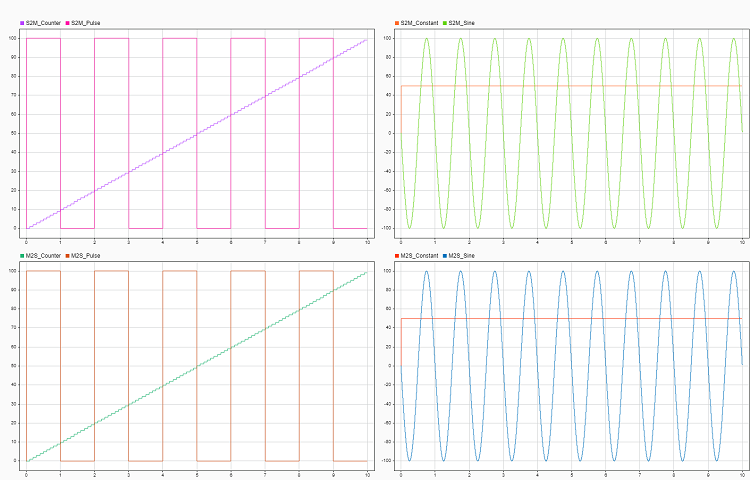

## Additional References

- [IO751 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io751)

- [IO752 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io752)